# 3.4 Сбор данных

**Практическое занятие**

## Импорт из Excel

В файле `students.xlsx` хранятся оценки студентов по самостоятельным работам. Считайте их виде таблицы (`table`) в переменную `G` (подсказка: `readtable()`)

Заголовки столбцов в файле подписаны по-русски, поэтому они считались некорректно. Измените в таблице `G` подписи столбцов на:

## Импорт из текстовых файлов

В файле `signal.txt` лежит записанный в ходе лабораторной работы сигнал. Хранится он в виде таблицы из двух столбцов - `Time` и `Signal`. Значения в строках разделены запятыми. Откройте этот файл в текстовом редакторе (MATLAB Editor) и изучите его структуру.

При помощи функции `readtable()` считайте сигнал из файла `signal.txt` в переменную `S`

Обратите внимание, что данные считались из файла некорректно из-за особого формата записи временных меток в столбце `Time`. Судя по всему, MATLAB использовал в качестве разделителей данных символы `,` и `:`. Такое поведение можно исправить, если вручную указать при импорте разделитель (`,`). Сделать это можно дополнительным аргументом функции `readtable` - '`Delimiter'`.

Импортируйте данные правильно, указав разделитель, в переменную `S`

Из-за особого формата записи времени, столбец `Time` импортировался как обычный текст (`cell string`), работать с такими временными метками при анализе неудобно. Сконвертируйте столбец `Time` в формат `datetime` (подсказка: `datetime()`)

После импорта данных, хочется на них взглянуть. Выведите первые 8 строк и заголовки таблицы `S` с помощью функции `head()`

Выведите сводную информацию о таблице `S` с помощью функции `summary()`

## Чтение текста из файлов

Иногда нужно просто считать текст из неструктурированного файла.

С помощью функции `fileread() `считайте весь текст из файла `info.txt` в переменную `info`

Команда `type` позволяет просто вывести текстовое содержимое файла на экран. Сделайте это

## Импорт изображений

Считайте с диска изображение `MATLAB-logo.jpg` с помощью функции `imread` в переменную `img`

Обратите внимание, что изображение хранится в памяти как матрица размерностью `564x614x3 `формата `uint8`. Каждый элемент матрицы - это яркость пикселя соответствующего цвета (Red, Green, Blue)

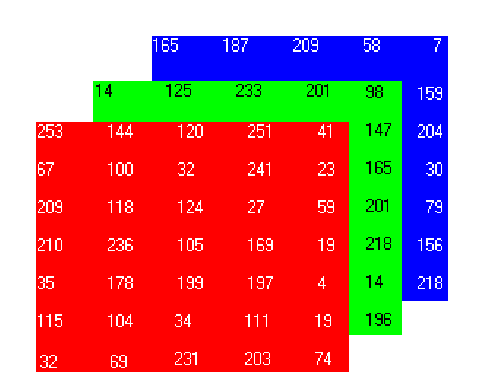

Выведите изображение `img` на экран с помощью функции `imshow()`

## Получение данных из интернета

С помощью функции `webread()` считайте по адресу `'https://restcountries.eu/rest/v2/region/europe'` информацию о европейских странах в переменную `data`

По умолчанию данные считываются в массив структур (`structure array`). Конвертируйте переменную `data` в таблицу (`table`) (подсказка: `struct2table()`)